# Waste Analysis Demo

Use the `ThermoeconomicModel` function to perform a waste analysis

### **(1) Read the data model**

file="D:\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
model=ThermoeconomicModel(file,'DiagnosisMethod','NONE','Debug',false);

### (2) Define Waste Analysis Parameters

Perform a waste analysis for State noIHE (without IHE), recycling 20% of heat in the conderser,

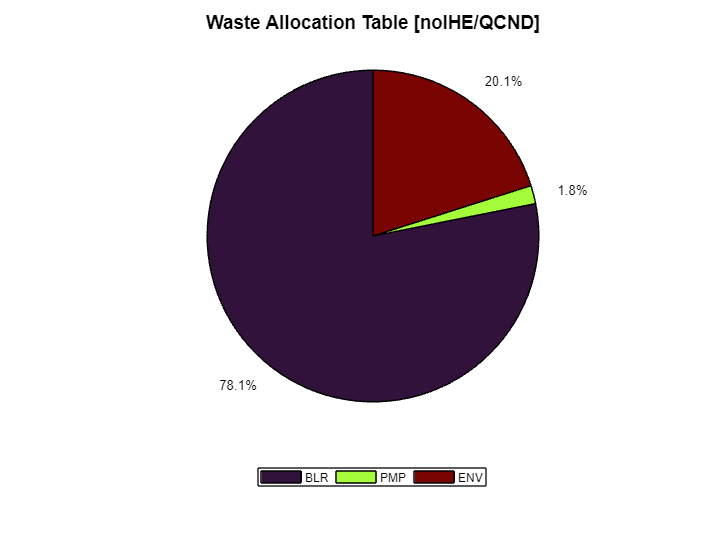

model.State='noIHE';
WasteFlows=convertCharsToStrings(model.WasteFlows);
model.ActiveWaste=convertStringsToChars(WasteFlows(1));
model.setWasteType(model.ActiveWaste,'HYBRID');
model.setWasteRecycled(model.ActiveWaste,0.2);
showGraph(model,cType.Tables.WASTE_ALLOCATION);

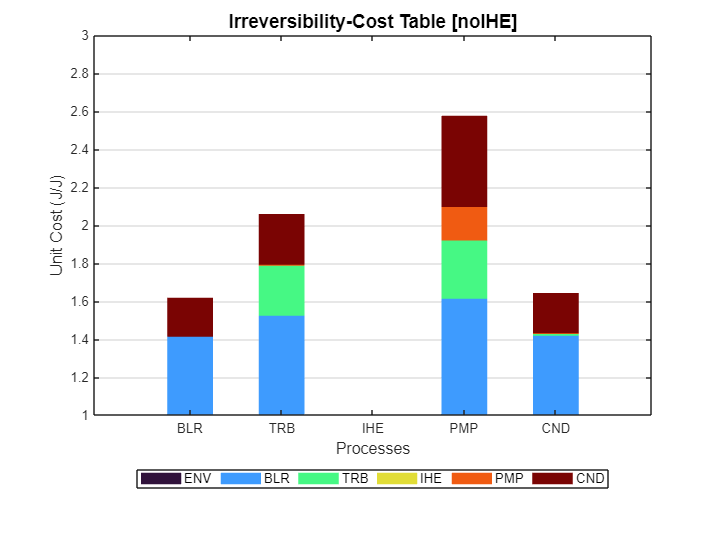

showGraph(model,cType.Tables.PROCESS_ICT);

### (3) Recycling Analysis

Show the recycling analysis graph

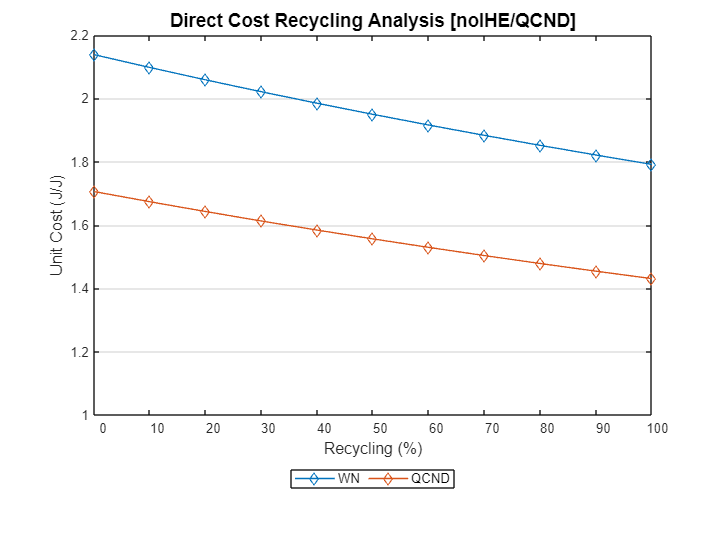

model.Recycling=true;
showGraph(model,cType.Tables.WASTE_RECYCLING_DIRECT);